## PhysicalChemicalOceanography PCO week 1

Calculate absolute salinity, conservative temperature, etc using TEOS-10

% safety first
close all;
clear all;

Add path to gsw_matlab if you haven't done so

addpath ../gsw_matlab_v3_06_13
addpath ../gsw_matlab_v3_06_13/html/
addpath ../gsw_matlab_v3_06_13/library/
addpath ../gsw_matlab_v3_06_13/pdf
addpath ../gsw_matlab_v3_06_13/thermodynamics_from_t/

The following vertical profiles from the North Pacific. 

SP = [ 34.5759  34.2870  34.5888  34.6589  34.6798  34.6910  34.6956 ]; 
t  = [ 19.5076   3.6302   1.9533   1.5661   1.4848   1.4989   1.5919 ]; 
p  = [       0     1010     2025     3045     4069     5098     6131 ];

## The first step is to convert practical salinity to absolute salinity using gsw_SA_from_SP

The input is practical salinity, pressure, longitude, and latitude 

SA = gsw_SA_from_SP(SP,p,-160,40); 
disp(['SA=',num2str(SA)])   % display the results

SA=34.7397      34.4673       34.776      34.8459      34.8661      34.8769       34.881


Plot the salinity profiles

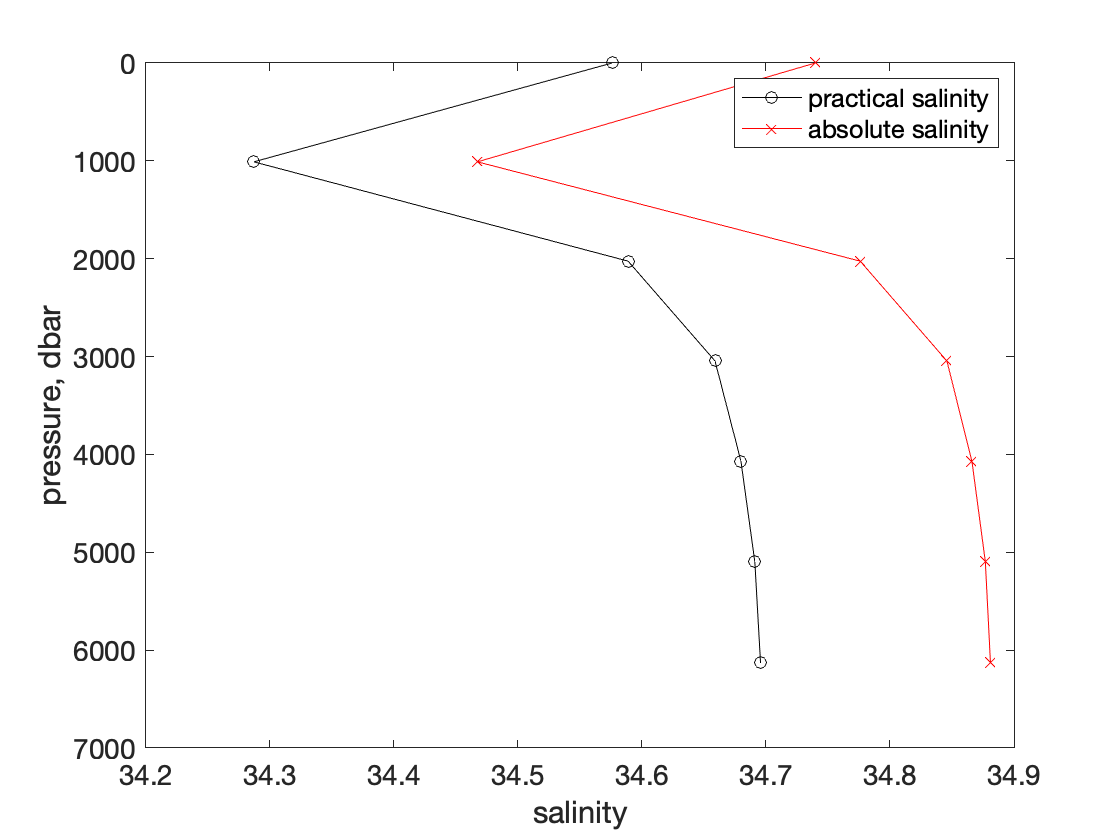

figure(1);
plot(SP,p,'ko-')   % plot SP as a function of pressure (depth)
hold on;
plot(SA,p,'rx-')   % plot SA as a function of pressure (depth) for visual comparison
hold off;
set(gca,'Ydir','reverse');
legend({'practical salinity' 'absolute salinity'})
xlabel('salinity')
ylabel('pressure, dbar');
set(gca,'fontsize',14);

## The second step is to convert in-situ temperature, t, into Conservative Temperature, CT, using the function "gsw_CT_from_t"

CT = gsw_CT_from_t(SA,t,p);
disp(['CT=',num2str(CT)]);   % display the results

CT=19.513      3.55875      1.81568      1.34341      1.15828       1.0517      1.00723


Plot the results

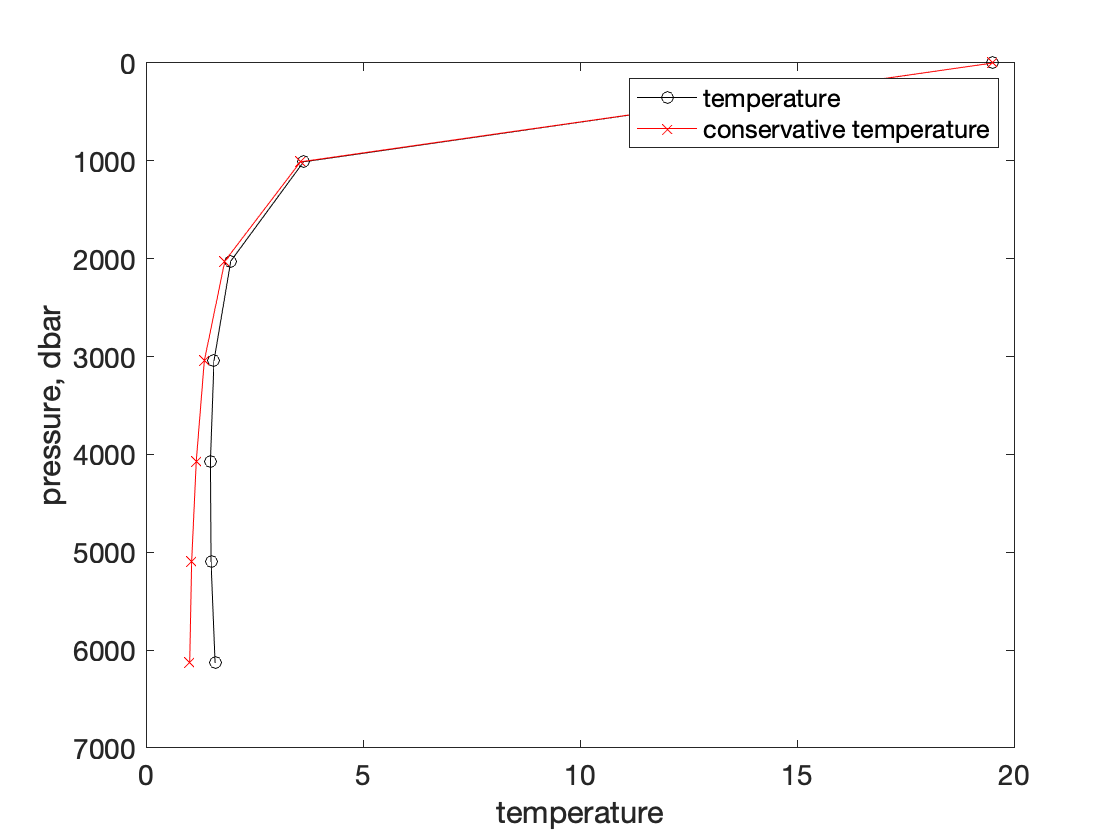

figure(2);
plot(t,p,'ko-');             % plot temperature as a function of pressure (depth)
hold on;
plot(CT,p,'rx-');            % plot conservative temperature as a function of pressure (depth) for visual comparison
hold off;
legend({'temperature' 'conservative temperature'})
xlabel('temperature')
ylabel('pressure, dbar')
set(gca,'Ydir','reverse');
set(gca,'fontsize',14);

At this point the data has been converted into SA and CT, which are the TEOS-10 salinity and temperature variables.

With these variables it is possible to compute the complete range of water column properties.

The first property to be demonstrated is density (rho) as a function of SA and CT. This is computed by using the function "gsw_rho".

rho = gsw_rho(SA,CT,p); % calculate density of seawater
disp(['rho=',num2str(rho)]); % display the results

rho=1024.5713      1031.9393      1037.0048      1041.6714      1046.1818      1050.5938       1054.904


Plot the results

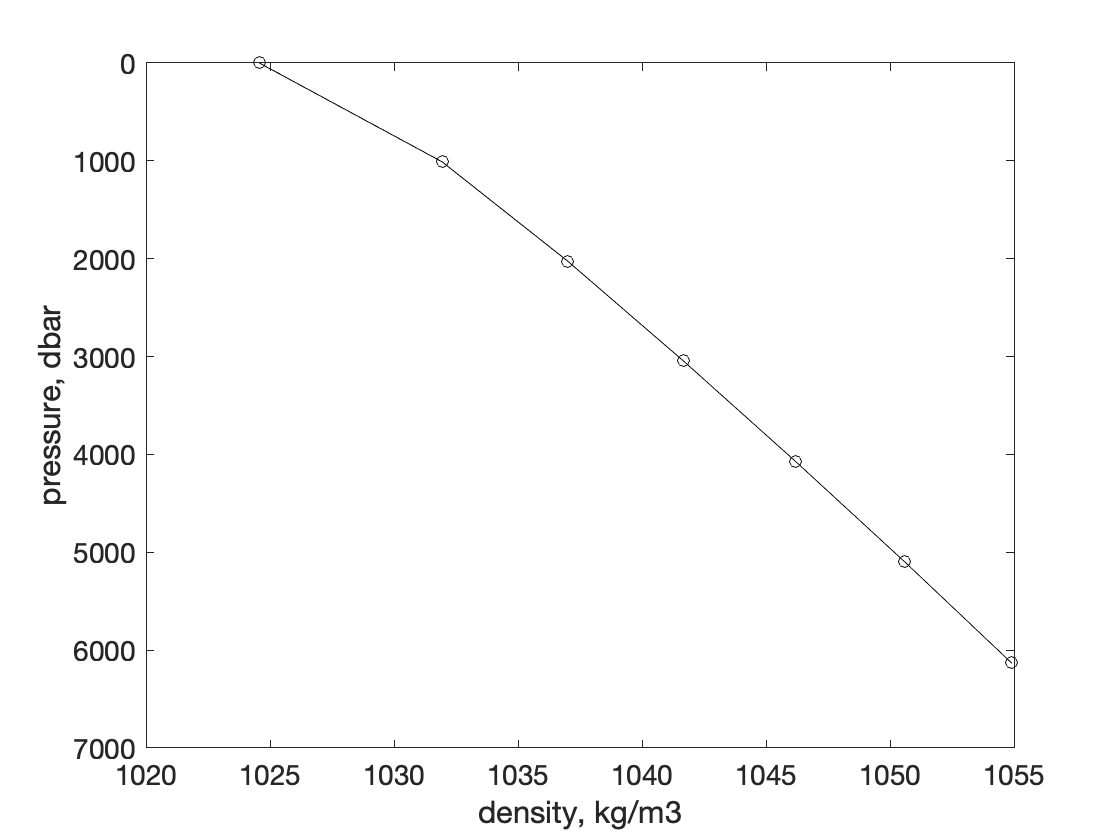

figure(3);
plot(rho,p,'ko-');  % plot density as a function of pressure (depth)
xlabel('density, kg/m3')
ylabel('pressure, dbar')
set(gca,'Ydir','reverse');
set(gca,'fontsize',14);

## Calculating the Conservative Temperature at which seawater freezes is done with the function "gsw_CT_freezing_poly"

This programme allows the user to choose the amount of air which the water contains.

When saturation_fraction is 0 the seawater contains no air, and when saturation_fraction is 1 the seawater is completely saturated with air.

The example below is to have the seawater air free.

CT_freezing = gsw_CT_freezing_poly(SA,p,0); %calculate the freezing point
disp(['CT_freezing=',num2str(CT_freezing)]);     % display the results

CT_freezing=-1.8917     -2.6679     -3.5202     -4.4002     -5.3175      -6.275     -7.2714


Plot the results

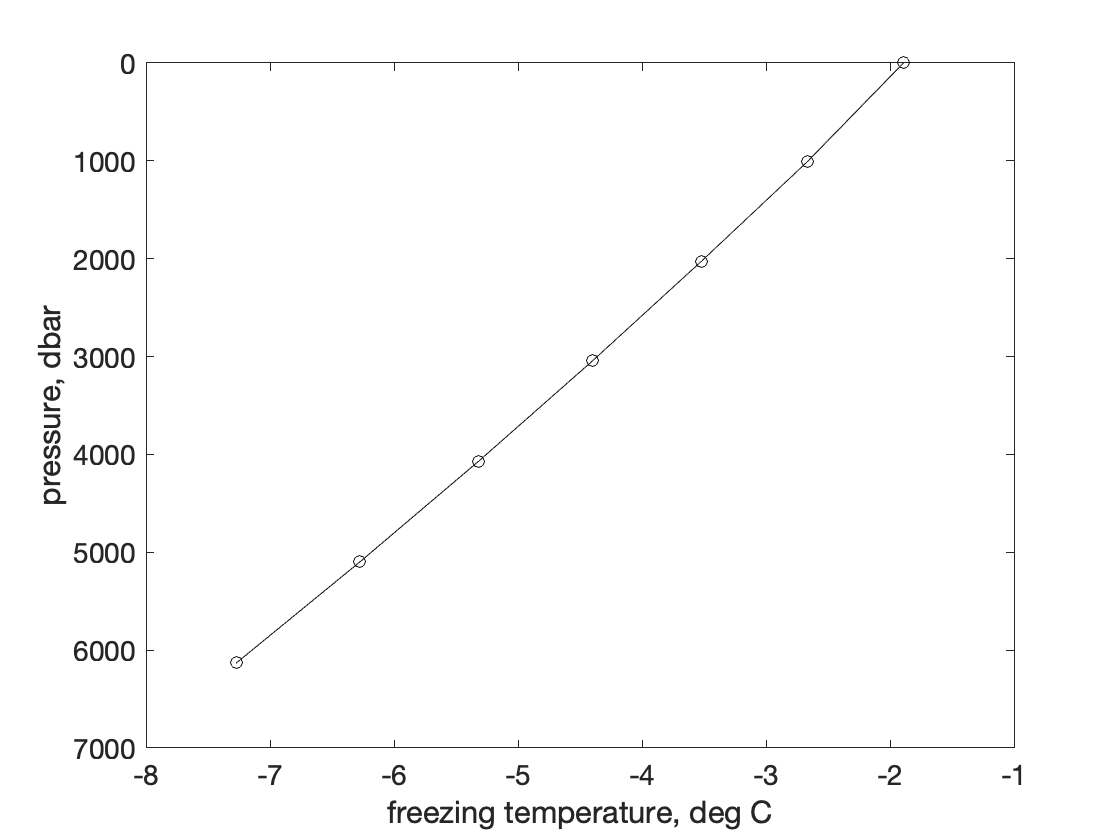

figure(4);
plot(CT_freezing,p,'ko-');              % plot density as a function of pressure (depth)
xlabel('freezing temperature, deg C');
ylabel('pressure, dbar');
set(gca,'Ydir','reverse');
set(gca,'fontsize',14);